# Author: Lucky Yerimah

%   Date: March 26 2020
%   For each problem:
%          Parameters declared
%          Cells created to hold ploted data
%          S, Sf, control moves computed
%          Plant is solved using ode45
%          Plots are then generated



%   Three tank plant data   
clear all
A = [-1, 0, 0; 1, -1, 0; 0, 1, -1];
B = [1;0;0];
C = [0,0,1];
D = 0;
sys = ss(A,B,C,D); % converting matrices to state space 
Gz = c2d(sys,0.5); % Discrete-time transfer function
x0 = [0;0;0]; % initial conditions for the states
[phi,gamma,Cz,Dz] = ssdata(Gz);
tbeng = 0;
deltaT = 0.5;
% Plant model 
Aplant = A;
Bplant = B;

## Problem One(a)

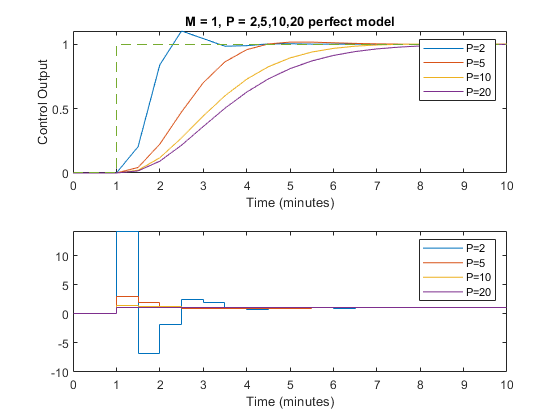


P = [2,5,10,20]; % set of prediction horizons
M = 1; % control horizon
rsp = 1; 
tend = 10;
time = tbeng:deltaT:tend;
Wu = 0; % input weighting

uk_1 = 0; % u(k-1)
x0 = [0;0;0]; % initial conditions for the states

% create cells to hold ploted data
y_out = cell(4,1); 
u_out = cell(4,1);

for n = 1:4 % loop for each prediction horizon 
    xdis(:,1) = x0;
    H = 0;
    
for j=1:P(n)
    H = H + Cz*phi^(j-1)*gamma;
    S(j,1) = H;
    Cphi(j,:) = Cz*phi^(j); 
end

Sf = zeros(P(n),M); % initial zeros for DMC matrix 
for j=1:M
    zero_DMC = zeros(j-1,1);
    Sf(:,j) = cat(1,zero_DMC,S(1:end+1-j,1)); %DMC 
end

Kmat = (Sf'*Sf+Wu)\Sf';


ydis(1) = C*xdis(:,1); % measured output
xmod(:,1) = zeros(3,1);
ymod(1) = Cz*xmod(:,1);
u_ini = 0;
d = ydis - ymod; % disturbance term for feedback control

for k = 1:length(time)-1
    
    % setpoint change at k = 3 (after one minute)
    if k == 1
        r(k) = 0;
        r_sp = zeros(P(n),1);
        free_resp = Cphi*xmod(:,k) + S*u_ini + ones(P(n),1)*d; % free response
        
    elseif k == 2
        r(k) = 0;
        r_sp = zeros(P(n),1)*rsp;
         free_resp = Cphi*xmod(:,k) + S*u(k-1) + ones(P(n),1)*d;
    else 
        r(k) = rsp; 
        r_sp = ones(P(n),1)*rsp;
        free_resp = Cphi*xmod(:,k) + S*u(k-1) + ones(P(n),1)*d;
    end

    E = r_sp - free_resp; % error term
    uf = Kmat*E; % vector of calculated control moves
    deltaU(k) = uf(1); % implement only first move
    
    if k == 1
        u(k) = u_ini + deltaU(k);
    else
        u(k) = u(k-1) + deltaU(k);
    end
    
 [tdummy,xdummy] = ode45('linodepar',[time(k) time(k+1)], xdis(:,k), [], Aplant, Bplant, u(k)  ); % ODE45 function   
    xdis(:,k+1) = xdummy(end,:);
    ydis(k+1) = C*xdis(:,k+1);
    xmod(:,k+1) = phi*xmod(:,k) + gamma*u(k);
    ymod(k+1) = Cz*xmod(:,k+1);
    d(k+1) = ydis(k+1) - ymod(k+1); % disturbance term
    
end
% make u and r same length as time
u(k+1) = u(k);
r(k+1) = r(k);

% Pass ydis and u to y_out cells to be used for generating plots
y_out{n} = ydis;
u_out{n} = u;

variables = {'H','S','Cphi','zero_DMC','Kmat','ydis','xdis','xmod','ymod', ...
    'd','free_resp','E', 'uf', 'deltaU'}; % combine all used variables to be cleared

clear(variables{:}) % clear variables before loop computes next prediction horizon

end


figure(100)

subplot(2,1,1)
plot(time,y_out{1})
hold on
plot(time,y_out{2})
plot(time,y_out{3})
plot(time,y_out{4})
stairs(time,r, '--')
hold off
legend('P=2','P=5','P=10','P=20')
xlabel('Time (minutes)')
ylabel('Control Output')
title("M = 1, P = 2,5,10,20 perfect model")

subplot(2,1,2)
stairs(time,u_out{1})
hold on
stairs(time,u_out{2})
stairs(time,u_out{3})
stairs(time,u_out{4})
hold off
xlabel('Time (minutes)')
legend('P=2','P=5','P=10','P=20')

## Problem One(b)

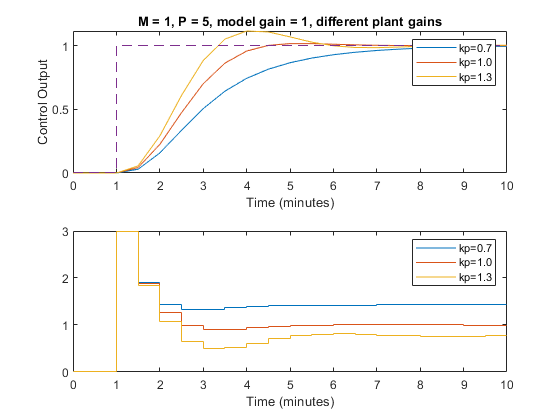


Bplant2 = {[0.7;0;0],[1.0;0;0],[1.3;0;0]}; % cell containing different plant gains (kp)
P = 5; % Prediction horizon
M = 1; % control horizon
rsp = 1;
tend = 10;
time = tbeng:deltaT:tend;
Wu = 0; % input weight
H = 0;
uk_1 = 0; % u(k-1)
x0 = [0;0;0]; % initial conditions for the states

% create cells to hold data for plotting for different plant gain (kp)
y_out2 = cell(3,1);
u_out2 = cell(3,1);
    
for j=1:P
    H = H + Cz*phi^(j-1)*gamma;
    S(j,1) = H;
    Cphi(j,:) = Cz*phi^(j); 
end

Sf = zeros(P,M); % initial zeros for DMC matrix 
for j=1:M
    zero_DMC = zeros(j-1,1);
    Sf(:,j) = cat(1,zero_DMC,S(1:end+1-j,1)); %DMC 
end

Kmat = (Sf'*Sf+Wu)\Sf';

for n = 1:3 % loop for the several plant gain 
    
xdis(:,1) = x0;
ydis(1) = C*xdis(:,1);
xmod(:,1) = zeros(3,1);
ymod(1) = Cz*xmod(:,1);
u_ini = 0;
d = ydis - ymod; % disturbance term
    
for k = 1:length(time)-1
    % step change occurs at k = 3 (after one minute)
    if k == 1
        r(k) = 0;
        r_sp = zeros(P,1);
        free_resp = Cphi*xmod(:,k) + S*u_ini + ones(P,1)*d(1); % free response
        
    elseif k == 2
        r(k) = 0;
        r_sp = zeros(P,1)*rsp;
         free_resp = Cphi*xmod(:,k) + S*u(k-1) + ones(P,1)*d(k);
    else 
        r(k) = rsp; % setpoint change at k = 3
        r_sp = ones(P,1)*rsp;
        free_resp = Cphi*xmod(:,k) + S*u(k-1) + ones(P,1)*d(k);
    end

    E = r_sp - free_resp; % error term 
    uf = Kmat*E; % control moves
    deltaU(k) = uf(1); % implementing only the first move
    
    if k == 1;
        u(k) = u_ini + deltaU(k);
    else
        u(k) = u(k-1) + deltaU(k);
    end
    
 [tdummy,xdummy] = ode45('linodepar',[time(k) time(k+1)], xdis(:,k), [], Aplant, Bplant2{n}, u(k)  ); % ODE45 function   
    xdis(:,k+1) = xdummy(end,:);
    ydis(k+1) = C*xdis(:,k+1);
    xmod(:,k+1) = phi*xmod(:,k) + gamma*u(k);
    ymod(k+1) = Cz*xmod(:,k+1);
    d(k+1) = ydis(k+1) - ymod(k+1);
    
end
u(k+1) = u(k);
r(k+1) = r(k);

% pass ydis and u to cells for generating plots
y_out2{n} = ydis;
u_out2{n} = u;

variables = {'tdummy','xdummy','xdis','ydis','xmod','ymod','d','u'};
clear(variables{:}) % combine all used variables to be cleared before loop computes next prediction horizon

end

figure(200)

subplot(2,1,1)
plot(time,y_out2{1})
hold on
plot(time,y_out2{2})
plot(time,y_out2{3})
stairs(time,r, '--')
hold off
legend('kp=0.7','kp=1.0','kp=1.3')
xlabel('Time (minutes)')
ylabel('Control Output')
title("M = 1, P = 5, model gain = 1, different plant gains")

subplot(2,1,2)
stairs(time,u_out2{1})
hold on
stairs(time,u_out2{2})
stairs(time,u_out2{3})
hold off
xlabel('Time (minutes)')
legend('kp=0.7','kp=1.0','kp=1.3')

## Problem Two(a)

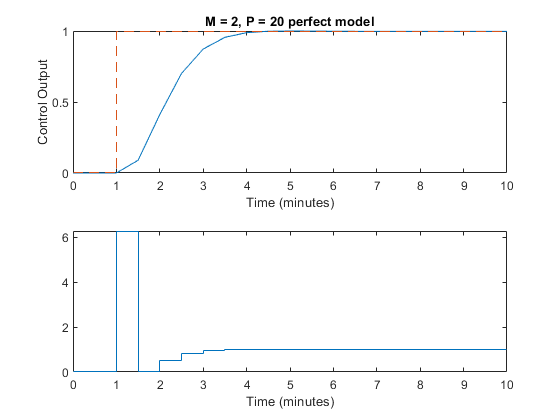


P = 20; % Prediction horizon
M = 2; % Control horizon
rsp = 1;
tend = 10;
time = tbeng:deltaT:tend;
Wu = 0;

uk_1 = 0; % u(k-1)
x0 = [0;0;0]; % initial conditions for the states

xdis(:,1) = x0;
H = 0;
    
for j=1:P
    H = H + Cz*phi^(j-1)*gamma;
    S(j,1) = H;
    Cphi(j,:) = Cz*phi^(j); 
end

Sf = zeros(P,M); % initial zeros for DMC matrix 
for j=1:M
    zero_DMC = zeros(j-1,1);
    Sf(:,j) = cat(1,zero_DMC,S(1:end+1-j,1)); %DMC 
end

Kmat = (Sf'*Sf+Wu)\Sf';


ydis(1) = C*xdis(:,1);
xmod(:,1) = zeros(3,1);
ymod(1) = Cz*xmod(:,1);
u_ini = 0;
d = ydis - ymod;

for k = 1:length(time)-1
    if k == 1
        r(k) = 0;
        r_sp = zeros(P,1);
        free_resp = Cphi*xmod(:,k) + S*u_ini + ones(P,1)*d;
        
    elseif k == 2
        r(k) = 0;
        r_sp = zeros(P,1)*rsp;
         free_resp = Cphi*xmod(:,k) + S*u(k-1) + ones(P,1)*d;
    else 
        r(k) = rsp; % setpoint change at k = 3
        r_sp = ones(P,1)*rsp;
        free_resp = Cphi*xmod(:,k) + S*u(k-1) + ones(P,1)*d;
    end

    E = r_sp - free_resp;
    uf = Kmat*E;
    deltaU(k) = uf(1);
    
    if k == 1
        u(k) = u_ini + deltaU(k);
    else
        u(k) = u(k-1) + deltaU(k);
    end
    
 [tdummy,xdummy] = ode45('linodepar',[time(k) time(k+1)], xdis(:,k), [], Aplant, Bplant, u(k)  ); % ODE45 function   
    xdis(:,k+1) = xdummy(end,:);
    ydis(k+1) = C*xdis(:,k+1);
    xmod(:,k+1) = phi*xmod(:,k) + gamma*u(k);
    ymod(k+1) = Cz*xmod(:,k+1);
    d(k+1) = ydis(k+1) - ymod(k+1);
    
end
u(k+1) = u(k);
r(k+1) = r(k);

figure(300)

subplot(2,1,1)
plot(time,ydis)
hold on
stairs(time,r, '--')
hold off
xlabel('Time (minutes)')
ylabel('Control Output')
title("M = 2, P = 20 perfect model")

subplot(2,1,2)
stairs(time,u)
xlabel('Time (minutes)')

## Problem Two(b)

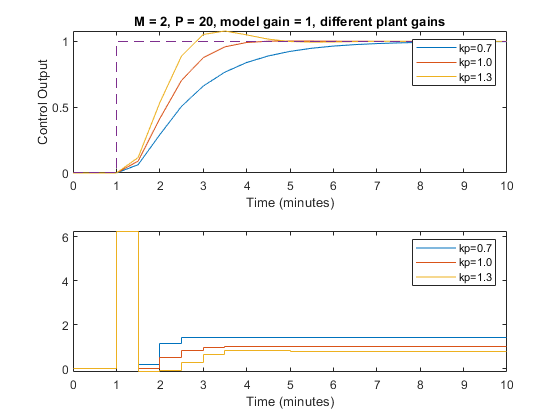


Bplant2 = {[0.7;0;0],[1.0;0;0],[1.3;0;0]}; % cell containing different plant gains (kp)
P = 20;
M = 2;
rsp = 1;
tend = 10;
time = tbeng:deltaT:tend;
Wu = 0;
H = 0;
uk_1 = 0; % u(k-1)
x0 = [0;0;0]; % initial conditions for the states
y_out3 = cell(3,1);
u_out3 = cell(3,1);
    
for j=1:P
    H = H + Cz*phi^(j-1)*gamma;
    S(j,1) = H;
    Cphi(j,:) = Cz*phi^(j); 
end

Sf = zeros(P,M); % initial zeros for DMC matrix 
for j=1:M
    zero_DMC = zeros(j-1,1);
    Sf(:,j) = cat(1,zero_DMC,S(1:end+1-j,1)); %DMC 
end

Kmat = (Sf'*Sf+Wu)\Sf';

for n = 1:3 % loop for the different plant gains (kp)
    
xdis(:,1) = x0;
ydis(1) = C*xdis(:,1);
xmod(:,1) = zeros(3,1);
ymod(1) = Cz*xmod(:,1);
u_ini = 0;
d = ydis - ymod;
    
for k = 1:length(time)-1
    if k == 1
        r(k) = 0;
        r_sp = zeros(P,1);
        free_resp = Cphi*xmod(:,k) + S*u_ini + ones(P,1)*d(1);
        
    elseif k == 2
        r(k) = 0;
        r_sp = zeros(P,1)*rsp;
         free_resp = Cphi*xmod(:,k) + S*u(k-1) + ones(P,1)*d(k);
    else 
        r(k) = rsp; % setpoint change at k = 3
        r_sp = ones(P,1)*rsp;
        free_resp = Cphi*xmod(:,k) + S*u(k-1) + ones(P,1)*d(k);
    end

    E = r_sp - free_resp;
    uf = Kmat*E;
    deltaU(k) = uf(1);
    
    if k == 1;
        u(k) = u_ini + deltaU(k);
    else
        u(k) = u(k-1) + deltaU(k);
    end
    
  % [tdummy,xdummy] = ode45(@(t,x) plantmodel(t,x,u(k),Bplant2(n)), [time(k) time(k+1)],xdis(:,k));
 [tdummy,xdummy] = ode45('linodepar',[time(k) time(k+1)], xdis(:,k), [], Aplant, Bplant2{n}, u(k)  ); % ODE45 function   
    xdis(:,k+1) = xdummy(end,:);
    ydis(k+1) = C*xdis(:,k+1);
    xmod(:,k+1) = phi*xmod(:,k) + gamma*u(k);
    ymod(k+1) = Cz*xmod(:,k+1);
    d(k+1) = ydis(k+1) - ymod(k+1);
    
end
u(k+1) = u(k);
r(k+1) = r(k);

y_out3{n} = ydis;
u_out3{n} = u;

variables = {'tdummy','xdummy','xdis','ydis','xmod','ymod','d','u'};
clear(variables{:})
end

figure(400)

subplot(2,1,1)
plot(time,y_out3{1})
hold on
plot(time,y_out3{2})
plot(time,y_out3{3})
stairs(time,r, '--')
hold off
legend('kp=0.7','kp=1.0','kp=1.3')
xlabel('Time (minutes)')
ylabel('Control Output')
title("M = 2, P = 20, model gain = 1, different plant gains")

subplot(2,1,2)
stairs(time,u_out3{1})
hold on
stairs(time,u_out3{2})
stairs(time,u_out3{3})
hold off
xlabel('Time (minutes)')
legend('kp=0.7','kp=1.0','kp=1.3')